# Model Predictive Control - Assigment

% Clearing variables
clearvars
close all

## Problem 1

## Question 1.1

The states are the masses, whih are changed by inlet and outlet mass flows. The manipulated variables are the mass flows that enter the distribution valve. The disturbance variables are the mass flows that enter the third and the fourth tank. The measured variables are the heights of the water levels in the tanks. The controlled variables are the height in tank 3 and tank 4.

## Question 1.2

Draw a block diagram to the system TODO

## Problem 2

Select parameter sets that make the system minimal phase or non-minimal phase. TODO

Select operating point TODO

## Question 2.1.1

According to the mass balance equation, for a given control volume, the change of the mass in the control volume is going to be the sum of the inflows and the outflows.


$$\dot{m} = \sum_i \rho q_{i}$$


The convenience is that the volume inflows have positive and the outflows have negative signs.

The valve outflows are given by the division of the flow done by the valve, which is described by a constant. Therefore the two outflows will have the values


$$q_{out,1} = \gamma F\\
q_{out,2} = (1-\gamma) F$$


where F is one of the manipulated variables.

Outflows of the tanks are described by Bernoulli law and the inner states.


$$q=a\sqrt{2gh}, \text{where} \quad h= \frac{m}{\rho A}$$


Therefore the first order state equations can be described as


$$\frac{dm_1}{dt}=\rho \gamma_1 F_1+\rho a \sqrt{2 g \frac{m_3}{\rho A}}-\rho a \sqrt{2 g \frac{m_1}{\rho A}}$$



$$\frac{dm_2}{dt}=\rho \gamma_2 F_2+\rho a \sqrt{2 g \frac{m_4}{\rho A}}-\rho a \sqrt{2 g \frac{m_2}{\rho A}}$$



$$\frac{dm_3}{dt}=\rho (1-\gamma_2) F_2-\rho a \sqrt{2 g \frac{m_3}{\rho A}}+\rho F_3$$



$$\frac{dm_4}{dt}=\rho (1-\gamma_1) F_1-\rho a \sqrt{2 g \frac{m_4}{\rho A}}+\rho F_4$$


## Question 2.1.2

The measurement equations for the tanks are the following in the deterministic case:


$$h_i = \frac{m_i}{\rho A}$$


## Question 2.1.3

The output equations are 


$$h_1 = \frac{m_1}{\rho A}\\
h_2 = \frac{m_2}{\rho A}$$


## Question 2.2.1

This time we have the same state equations as the ones developed in Question 2.1.1, but with more information about the (deterministic) disturbances: they are piece-wise constant.


$$F_3(t) = F_{3,k} \quad \text{for} \quad t_k \leq t<t_{k+1}\\
F_4(t) = F_{4,k} \quad \text{for} \quad t_k \leq t<t_{k+1}$$


## Question 2.2.2

There is Gaussian noise on the measurement signals. It can be modelled such that


$$h_i = \frac{m_i}{\rho A}+v(t), \text{where} \quad v(t) \tilde{} N(0,R_{vv})$$


## Question 2.2.3

The output equations have not been changed with regard to the deterministic equations.

## Question 2.3.1

Having the $F_3$ and $F_4$ as Brownian motion, we can get the elements $\rho F_i dt$ in the equation of dt. This means that the differential of the state is going to be proportial to the Brownian motion $F_i \tilde{} N(F_{i,k},R_{ww})$

## Question 2.3.2

The output equations have not been changed compared to Question 2.2.2.

## Question 2.3.3

The output equations have not been changed compared to Question 2.2.3.

# Problem 3

Four tank system changable parameters.

% First we make an instance of the four tank system object.
fts = FourTankSystem;
% Choice for valve division
% NONMINIMAL PHASE TODO
gamma = [0.65; 0.55]; 
% Initial values of states
initials.m = zeros(4,1);
% Options of the solver
ODEoptions = [];

Initialization of the instance.

% Initialization of the Four Tank System object
fts.initialize(gamma,initials,ODEoptions);
% The steady state input signals 
ssInput  = [250; 325; 0; 0];
% The initialization guess for the steady state solution
initialGuess = [5000; 5000; 5000; 5000];  
% Calculation of the steady state
fts.steadyState(ssInput,initialGuess)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the default value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



## Question 3.1.1

% Initialization of the equilibrium
fts.m = fts.ms;
% Initialization of the records
fts.record.t = [];
fts.record.x = [];

Simulation of the plant for different deviations from the current equilibrium input.

% Simulation
Ts = 1;
itmax = 500;
t = 0:Ts:itmax*Ts;
% Deviation (from input steady state)
deviation = zeros(4,length(t));
deviation(1,itmax*0.05:itmax*0.15) = 1.1;
deviation(1,itmax*0.25:itmax*0.35) = 1.25;
deviation(1,itmax*0.55:itmax*0.75) = 1.5;
deviation(1,itmax*0.85:itmax*0.95) = linspace(1,1.25,itmax*0.1+1);
deviation(2,itmax*0.1:itmax*0.2) = 1.1;
deviation(2,itmax*0.3:itmax*0.4) = 1.25;
deviation(2,itmax*0.5:itmax*0.6) = 1.5;
deviation(2,itmax*0.7:itmax*0.8) = linspace(1,1.25,itmax*0.1+1);
for it = 1:length(t)-1
    fts.timestep([t(it); t(it+1)],ssInput.*deviation(:,it));
end

Now the results are plotted: the measurements should be plotted TODO

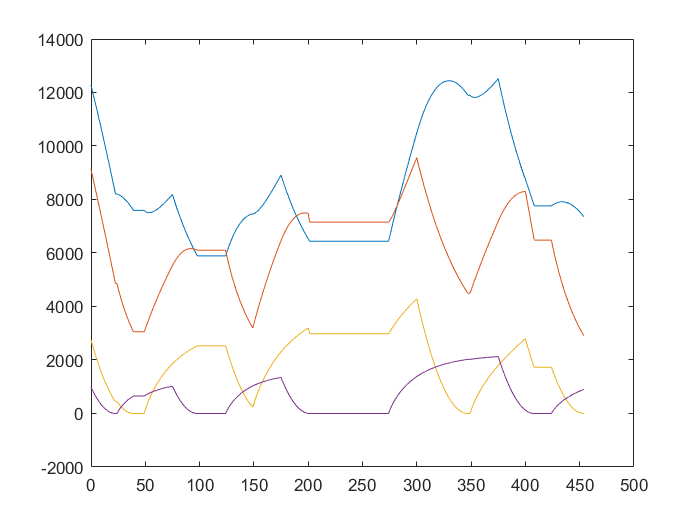

plot(fts.record.t,fts.record.x)